Compute the best linear approximation of $f^*(x)$ to $f(x)=x^3$ with respect to the euclidean norm in the subspace $P_1[-1,+1]$ of 2n degree trigonometric polynomials over $[-1;+1]$ with $M_n=P_1[-1,1]=span\{1,\cos(x),\sin(x)\}$

%This is how we compute it with respect to the euclidean norm in the
%subspace P1 = span{1,x}
syms x real;
M=[sym(1) x];
f=x^3;
A=int(M'*M,-1,1)

$$A = \left(\begin{array}{cc} 2 & 0\\ 0 & \frac{2}{3} \end{array}\right)$$

b=int(M'*f,-1,1)

$$b = \left(\begin{array}{c} 0\\ \frac{2}{5} \end{array}\right)$$

c=A\b

$$c = \left(\begin{array}{c} 0\\ \frac{3}{5} \end{array}\right)$$

fstar=M*c

$$fstar = \frac{3\,x}{5}$$


disp([f fstar])

$$\left(\begin{array}{cc} x^{3} & \frac{3\,x}{5} \end{array}\right)$$

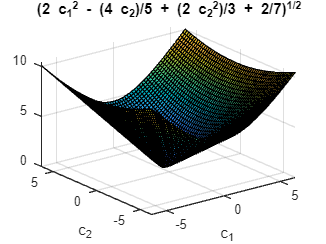


syms x c1 c2 real;
er_min=sqrt(int((f-fstar)^2,-1,1));
er=sqrt(int((f-(c1+c2*x))^2,-1,1));
ezsurf(er); hold on; AX=axis;
axis(AX)

G=gradient(er); S=solve(G)

S = struct with fields:
    c1: 0
    c2: 3/5


syms x;
f=@(x) x^3;
M=[sym(1) cos(x) sin(x)];
%f* is given by c_1 + c_2 cos(x) + c_3 sin(x)
A=int(M'*M,-1,1)

$$A = \left(\begin{array}{ccc} 2 & 2\,\sin\left(1\right) & 0\\ 2\,\sin\left(1\right) & \frac{\sin\left(2\right)}{2}+1 & 0\\ 0 & 0 & 1-\frac{\sin\left(2\right)}{2} \end{array}\right)$$

b=int(M'*f,-1,1)

$$b = \left(\begin{array}{c} 0\\ 0\\ 10\,\cos\left(1\right)-6\,\sin\left(1\right) \end{array}\right)$$

c=A\b

$$c = \left(\begin{array}{c} 0\\ 0\\ -\frac{4\,\left(5\,\cos\left(1\right)-3\,\sin\left(1\right)\right)}{\sin\left(2\right)-2} \end{array}\right)$$

fstar=M*c

$$fstar = -\frac{4\,\sin\left(x\right)\,\left(5\,\cos\left(1\right)-3\,\sin\left(1\right)\right)}{\sin\left(2\right)-2}$$


er_min=sqrt(int((f-fstar)^2,-1,1)); %Error
er=sqrt(int((f-(c1+c2*x))^2,-1,1)); %Error
simplify(er_min)

$$ans = \frac{\sqrt{14}\,\sqrt{419\,\cos\left(4\right)-896\,\cos\left(2\right)+2624\,\sin\left(2\right)+224\,\sin\left(4\right)-2315}}{7\,\sqrt{9-8\,\sin\left(2\right)-\cos\left(4\right)}}$$

simplify(er)

$$ans = \sqrt{2\,{c_{1}}^{2}+\frac{2\,{c_{2}}^{2}}{3}-\frac{4\,c_{2}}{5}+\frac{2}{7}}$$

syms x;
syms c [3 1];
M=[1 cos(x) sin(x)];
f_star=dot(c,M)

$$f\_star = \bar{c_{1}}+\bar{c_{2}}\,\cos\left(x\right)+\bar{c_{3}}\,\sin\left(x\right)$$

e=f-f_star

$$e = x^{3}-\bar{c_{2}}\,\cos\left(x\right)-\bar{c_{3}}\,\sin\left(x\right)-\bar{c_{1}}$$

eq=int(e*M,x,-1,1)

$$eq = \left(\begin{array}{ccc} -2\,\bar{c_{1}}-2\,\sin\left(1\right)\,\bar{c_{2}} & -\bar{c_{2}}\,\left(\frac{\sin\left(2\right)}{2}+1\right)-2\,\sin\left(1\right)\,\bar{c_{1}} & 10\,\cos\left(1\right)-6\,\sin\left(1\right)+\bar{c_{3}}\,\left(\frac{\sin\left(2\right)}{2}-1\right) \end{array}\right)$$

coefficients=solve(eq,c)

coefficients = struct with fields:
    c1: 0
    c2: 0
    c3: -(10*cos(1) - 6*sin(1))/(sin(2)/2 - 1)


f_star=simplify(coefficients.c1 + coefficients.c2*cos(x) + coefficients.c3*sin(x))

$$f\_star = -\frac{4\,\sin\left(x\right)\,\left(5\,\cos\left(1\right)-3\,\sin\left(1\right)\right)}{\sin\left(2\right)-2}$$


er_min=sqrt(int((f-f_star)^2,-1,1)); %Error
er=sqrt(int((f-(c1+c2*cos(x)+c3*sin(x)))^2,-1,1)); %Error
simplify(er_min)

$$ans = \frac{\sqrt{14}\,\sqrt{419\,\cos\left(4\right)-896\,\cos\left(2\right)+2624\,\sin\left(2\right)+224\,\sin\left(4\right)-2315}}{7\,\sqrt{9-8\,\sin\left(2\right)-\cos\left(4\right)}}$$

simplify(er)

$$ans = \sqrt{12\,c_{3}\,\sin\left(1\right)-20\,c_{3}\,\cos\left(1\right)+\frac{{c_{2}}^{2}\,\sin\left(2\right)}{2}-\frac{{c_{3}}^{2}\,\sin\left(2\right)}{2}+2\,{c_{1}}^{2}+{c_{2}}^{2}+{c_{3}}^{2}+4\,c_{1}\,c_{2}\,\sin\left(1\right)+\frac{2}{7}}$$

Adesso passiamo all'esercizio: confrontare graficamente le due approssimazioni

syms x real;
f=x^3;

%Sol 1
M1=[sym(1) x];
A1=int(M1'*M1,-1,1)

$$A1 = \left(\begin{array}{cc} 2 & 0\\ 0 & \frac{2}{3} \end{array}\right)$$

b1=int(M1'*f,-1,1)

$$b1 = \left(\begin{array}{c} 0\\ \frac{2}{5} \end{array}\right)$$

c1=A1\b1;
fstar1=M1*c1

$$fstar1 = \frac{3\,x}{5}$$

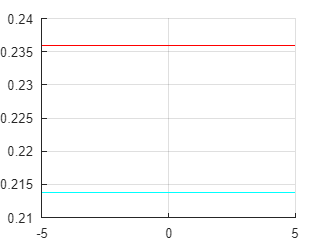

er_min1=sqrt(int((f-fstar1)^2,-1,1));

%Sol 2
M2=[sym(1) cos(x) sin(x)];
A2=int(M2'*M2,-1,1); b2=int(M2'*f,-1,1);
c2=A2\b2;
fstar2=M2*c2;
er_min2=sqrt(int((f-fstar2)^2,-1,1));

%Visualize
figure; hold on; grid on;
fplot(er_min1,'Color','c');
fplot(er_min2,'Color','r');
hold off;

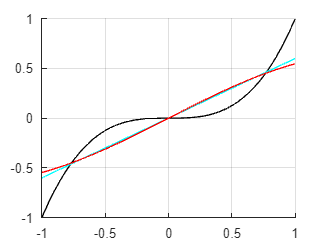


%Osservazione 1: l'errore di (1) è più basso di (2)

figure; hold on; grid on;
fplot(f,[-1,1],'Color','black');
fplot(fstar1,[-1 1],'Color','c');
fplot(fstar2,[-1 1],'Color','r');
hold off; 

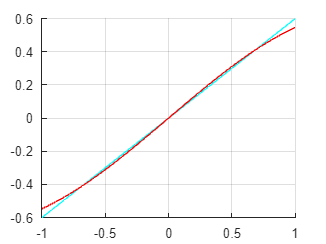

%Specifico in fplot l'intervallo -1,1 perché le approssimazioni 
% sono state computate rispetto a quell'intervallo

%Osservazione 2: La funzione fstar1 è quella che più si "avvicina" pur
%essendo comunque non sufficientemente vicina a x^3

figure; hold on; grid on;
fplot(fstar1,[-1 1],'Color','c');
fplot(fstar2,[-1 1],'Color','r');
hold off;


min(er_min1,er_min2)

$$ans = \frac{2\,\sqrt{2}\,\sqrt{7}}{35}$$

Now a variant of this exercise where the span isn't an orthonormal basis.

First an example "guided" to understand

syms x;
f=x^3;
M=[sym(1) x];

%Orthonormalizza M
nphi1=sqrt(norm(int(M(1)^2,-1,1)))

$$nphi1 = \sqrt{2}$$

nphi2=sqrt(norm(int(M(2)^2,-1,1)))

$$nphi2 = \frac{\sqrt{2}\,\sqrt{3}}{3}$$


phi1=M(1)/sqrt(norm(int(M(1)^2,-1,1)))

$$phi1 = \frac{\sqrt{2}}{2}$$

phi2=M(2)/sqrt(norm(int(M(2)^2,-1,1)))

$$phi2 = \frac{\sqrt{2}\,\sqrt{3}\,x}{2}$$

M=[phi1 phi2]

$$M = \left(\begin{array}{cc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} \end{array}\right)$$


A=int(M'*M,-1,1); %Calcola A come <phi_i,phi_j>
b=int(M'*f,-1,1); %Calcola A^T*f
c=A\b; %Risolvi A^TAc=A^Tf
fstar=M*c; %Approssimazione
disp(fstar)

$$\frac{\sqrt{2}\,\sqrt{3}\,\sqrt{6}\,x}{10}$$

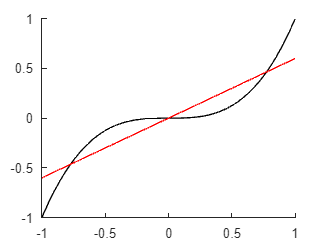


clf; hold on;
fplot(f,[-1,1],'Color','black');
fplot(fstar,[-1 1],'Color','r');
hold off;

Next, the true exercise

Find the best linear approximation of $f^*$ of $f(x)=x^3$ with respect to euclidean norm 2 $(||\cdot||)$ on the subspace $P_1[-\pi,+\pi]$ of a second degree trigonometric polynomial in the same interval by orthonormalizing at first the subspace basis $1,\cos(x),\sin(x)$ and compare the obtained solution with the previous one not orthonormalized. 

syms x;
f=x^3;
M=[1 cos(x) sin(x)]; Mn=[1 cos(x) sin(x)];
%ortonormalizzazione
for i=1:3
    n=sqrt(norm(int(M(i)^2,-1,1)));
    Mn(i)=Mn(i)/n;
end
disp([M Mn])

$$\left(\begin{array}{cccccc} 1 & \cos\left(x\right) & \sin\left(x\right) & \frac{\sqrt{2}}{2} & \frac{\cos\left(x\right)}{{\left({\left(\frac{\sin\left(2\right)}{2}+1\right)}^{2}\right)}^{1/4}} & \frac{\sin\left(x\right)}{{\left({\left(\frac{\sin\left(2\right)}{2}-1\right)}^{2}\right)}^{1/4}} \end{array}\right)$$


%A^TAc*=fA^T - For M
A=int(M'*M,-1,1);
b=int(M'*f,-1,1);
c=A\b;
fstar=M*c;

%A^TAc*=fA^T for Mn
An=int(Mn'*Mn,-1,1);
bn=int(Mn'*f,-1,1);
cn=An\bn;
fstarN=Mn*cn;

%Or
fstarN2=int(Mn'*f,-1,1);
disp(simplify(sum(fstarN2)));

$$\frac{\sqrt{2}\,\left(10\,\cos\left(1\right)-6\,\sin\left(1\right)\right)}{{\left({\left(\sin\left(2\right)-2\right)}^{2}\right)}^{1/4}}$$

disp(simplify(fstarN));

$$-\frac{4\,\sin\left(x\right)\,\left(5\,\cos\left(1\right)-3\,\sin\left(1\right)\right)}{\sin\left(2\right)-2}$$


%Visualize results
disp([fstar fstarN])

$$\left(\begin{array}{cc} -\frac{4\,\sin\left(x\right)\,\left(5\,\cos\left(1\right)-3\,\sin\left(1\right)\right)}{\sin\left(2\right)-2} & -\frac{4\,\sin\left(x\right)\,{\left(\frac{{\left(\sin\left(2\right)-2\right)}^{2}}{4}\right)}^{1/4}\,\left(5\,\cos\left(1\right)-3\,\sin\left(1\right)\right)}{{\left({\left(\frac{\sin\left(2\right)}{2}-1\right)}^{2}\right)}^{1/4}\,\left(\sin\left(2\right)-2\right)} \end{array}\right)$$

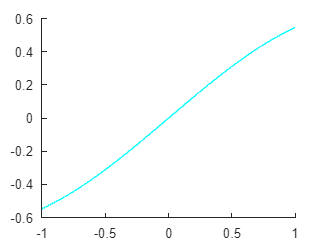

clf; figure; hold on; 
fplot(fstar,[-1,1],'Color','red');
fplot(fstarN,[-1,1],'Color','cyan');
hold off;

Now the following exercise: find the best fit circle of a sample of N data in R^2. The problem an incompatible system of the following equation: $(x-a)^2+(y-b)^2=R^2$ 

which lead to the system:


$$[2x_i \; 2y_i \; 1] \{a\;  b \; R^2 - a^2 - b^2\}^T = x^2_i + y^2_i$$


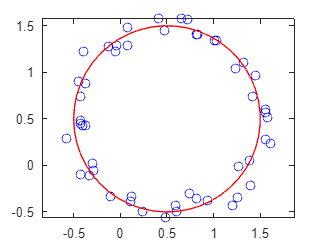

X0=0.5; Y0=0.5; r0=1;
N=50; %=,100,150,200 num. of samples
t=linspace(-pi,pi,N)';
Xi=X0+r0*cos(t); % exact 
Yi=Y0+r0*sin(t);
perc=0.15;
xi=Xi+perc*(2*rand(N,1)-1);
yi=Yi+perc*(2*rand(N,1)-1);
plot(xi,yi,'ob'); axis equal
hold on; plot(Xi,Yi,'r')



vecones=ones(50,1);
v=[2*xi 2*yi vecones];
syms a b R;
A=[a; b; (R^2-a^2-b^2)];
f=xi.^2 + yi.^2;
equation=v*A-f==0

sol=solve(equation,[a b R])

sol = struct with fields:
    a: [0×1 sym]
    b: [0×1 sym]
    R: [0×1 sym]


a_fit = double(sol.a);
b_fit = double(sol.b);
R_fit = double(sol.R);
disp(['Fitted center: (', num2str(a_fit), ', ', num2str(b_fit), ')']);

Fitted center: (, )


disp(['Fitted radius: ', num2str(R_fit)]);

Fitted radius: 


% Parameters
X0 = 0.5; % Center X coordinate
Y0 = 0.5; % Center Y coordinate
r0 = 1;   % Radius
N = 50;   % Number of samples
perc = 0.15; % Noise percentage

% Generate true circle points
t = linspace(-pi, pi, N)'; % Angles
Xi = X0 + r0 * cos(t); % True X coordinates
Yi = Y0 + r0 * sin(t); % True Y coordinates

% Add noise to the data
xi = Xi + perc * (2 * rand(N, 1) - 1);
yi = Yi + perc * (2 * rand(N, 1) - 1);

% Plot the noisy data and the true circle
figure;
plot(xi, yi, 'ob'); % Plot noisy data
hold on;
plot(Xi, Yi, 'r'); % Plot true circle
axis equal;

% Setup the matrix for circle fitting
vecones = ones(N, 1); % Vector of ones for the constant term
v = [2 * xi, 2 * yi, vecones]; % Matrix for least squares problem
f = xi.^2 + yi.^2; % Function vector

% Analogous Solutions for the problem
xLS=v\f %LS Solution 

xLS =     0.4872
    0.4882
    0.5715


xNe= (v'*v)\(v'*f)

xNe =     0.4872
    0.4882
    0.5715


xLN=pinv(v)*f

xLN =     0.4872
    0.4882
    0.5715



a=xLS(1); b=xLS(2);
r=sqrt(xLS(1)+xLS(2)) %compute r by knowing a+b

r = 0.9876

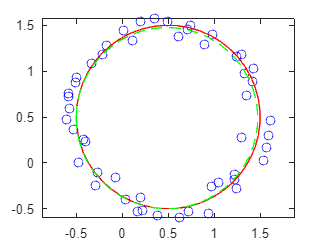


%Construct the x and y coordinates of the circle
fit_x=xLS(1)+r*cos(t);
fit_y=xLS(2)+r*sin(t);

plot(fit_x,fit_y,'g--');

Esercizio precedente ma considerando l'equazione:


$$x^2+y^2+\alpha x+ \beta y+ \gamma=0$$


%SAME AS BEFORE!
% Parameters
X0 = 0.5; % Center X coordinate
Y0 = 0.5; % Center Y coordinate
r0 = 1;   % Radius
N = 50;   % Number of samples
perc = 0.10; % Noise percentage

% Generate true circle points
t = linspace(-pi, pi, N)'; % Angles
Xi = X0 + r0 * cos(t); % True X coordinates
Yi = Y0 + r0 * sin(t); % True Y coordinates

% Add noise to the data
xi = Xi + perc * (2 * rand(N, 1) - 1);
yi = Yi + perc * (2 * rand(N, 1) - 1);

% Plot the noisy data and the true circle
figure;
plot(xi, yi, 'ob'); % Plot noisy data
hold on;
plot(Xi, Yi, 'r'); % Plot true circle
axis equal;

%-------------------------------------
v=[xi yi ones(N,1)]

v =    -0.4711    0.5926    1.0000
   -0.5161    0.3815    1.0000
   -0.4050    0.2506    1.0000
   -0.4204    0.0711    1.0000
   -0.4012    0.0071    1.0000
   -0.2136   -0.0733    1.0000
   -0.1432   -0.1599    1.0000
   -0.1135   -0.3027    1.0000
    0.0061   -0.3817    1.0000
    0.1126   -0.3168    1.0000


f=xi.^2+yi.^2

f =     0.5732
    0.4119
    0.2268
    0.1817
    0.1610
    0.0510
    0.0460
    0.1045
    0.1457
    0.1131



xBS=v\f;
alpha=xBS(1)

alpha = 1.0147

beta=xBS(2)

beta = 1.0234

gamma=xBS(3)

gamma = 0.4797


h=alpha/2

h = 0.5074

k=beta/2

k = 0.5117

r= sqrt( alpha^2+ beta^2 - 4*gamma )*0.5

r = 0.1988

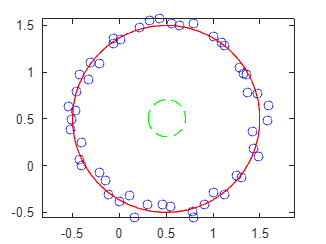

fit_x2 = alpha/2 + r * cos(t); % X coordinates of the circle
fit_y2 = alpha/2 + r * sin(t); % Y coordinates of the circle

plot(fit_x2, fit_y2, '--g'); % Plot noisy data

Verify, by means of MATLAB Symbolic Math Toolbox, that $\min ||X_{LS}||_2$ is reached by the LS solution computed by pinv()

A=[1 2 3 4; 5 6 7 8]'; b=[1 0 1 0]';
xLN=pinv(A)*b;

norm_xLN= norm(A*xLN-b)

norm_xLN = 0.8944


xBS=A\b;
norm_xBS=norm(A*xLN-b)

norm_xBS = 0.8944


rank(A'*A)

ans = 2



%------------------------
syms x1 x2 x3 x4 real
syms a11 a12 a13 a14 a21 a22 a23 a24 b1 b2 b3 b4 real

A = [a11, a12, a13, a14; a21, a22, a23, a24]'

$$A = \left(\begin{array}{cc} a_{11} & a_{21}\\ a_{12} & a_{22}\\ a_{13} & a_{23}\\ a_{14} & a_{24} \end{array}\right)$$

b = [b1 b2 b3 b4]'

$$b = \left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3}\\ b_{4} \end{array}\right)$$

x = [x1; x2];
rank(A'*A)

ans = 2

r=A*x-b;

norm_r_squared=simplify(r.'*r);
grad_x = gradient(norm_r_squared, x);
xLN=solve(grad_x==0,x);

x1=xLN.x1;
x2=xLN.x2;

x_pinv = pinv(A)*b;
xLN=simplify([x1;x2]); x_pinv=simplify(x_pinv);

xLN-x_pinv

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Solve by means of Least Square the following fitting problem:

speed v (m/s): `v=[10 20 30 40 50 60 70 80]';`

force F (N): `F=[25 70 380 550 610 1220 830 1450]';`

modeled by power function: $y = f(x) = ax^b$, $a,b \in \mathbb R$

Note that the fitting model is non-linear

syms a b x;
f=@(x) a*x^b;
v=[10 20 30 40 50 60 70 80]';
F=[25 70 380 550 610 1120 830 1450]';

logy=log(F);
logv=log(v);
A = [ones(size(logv)), logv];

coeffs=A\logy;
disp(coeffs);

   -1.2630
    1.9727



a=exp(coeffs(1));
b=coeffs(2);
disp([a b]);

    0.2828    1.9727




%Verify
ystar=a.*(v.^b)

ystar = 1.0e+03 *

    0.0266
    0.1042
    0.2319
    0.4091
    0.6353
    0.9102
    1.2337
    1.6055



% X_LS solution by using SVD decomposition
[U,S,V]=svd(v,'econ')

U =     0.0700
    0.1400
    0.2100
    0.2801
    0.3501
    0.4201
    0.4901
    0.5601


S = 142.8286

V = 1

xstar=V*[1./diag(S)]*U'*F;
disp(xstar);

   15.0417




%Chat GPT Solution
X = log(v);
Y = log(F);
A = [ones(size(X)), X];  % [1 X]

%Rewriting as Y = [A b][1 X]^T
coefficients=A\Y;
log_a=coefficients(1); b=coefficients(2);
a=exp(log_a);
disp([a b]);

    0.2828    1.9727




F_fit = a * v.^b;

%Compute the residual r=b-Ax*
%Error between the model prediction and actual data
residual=norm(Y - A* (A\Y)) 

residual = 0.8401

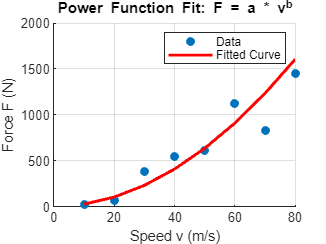


%Plot
figure;
scatter(v, F, 'o', 'filled');
hold on;
plot(v, F_fit, '-r', 'LineWidth', 2);
xlabel('Speed v (m/s)');
ylabel('Force F (N)');
title('Power Function Fit: F = a * v^b');
legend('Data', 'Fitted Curve');
grid on;